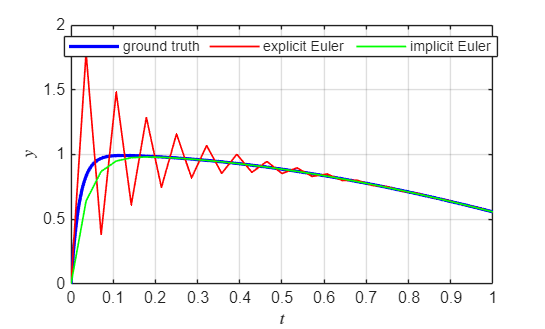

y = @(t) (50/2501)*(sin(t) + 50*cos(t)) - (2500/2501)*exp(-50*t);
f = @(t, y) -50 * (y - cos(t));
t0 = 0;
y0 = 0;
t1 = 1;
N = 29;
t = linspace(t0, t1, 500);
grid_t = linspace(t0, t1, N);
grid_y_euler = zeros(1, N);
grid_y_euler(1) = y0;
grid_y_euler_implicit = zeros(1, N);
grid_y_euler_implicit(1) = y0;
h = grid_t(2) - grid_t(1);
for n = 1 : N - 1
    grid_y_euler(n + 1) = grid_y_euler(n) + f(grid_t(n), grid_y_euler(n)) * h;
    grid_y_euler_implicit(n + 1) = (grid_y_euler_implicit(n) + 50 * h * cos(grid_t(n + 1))) / (50 * h +1);
end

plot(t, y(t), 'b', 'LineWidth', 2);
hold on;
plot(grid_t, grid_y_euler, 'r', 'LineWidth', 1);
plot(grid_t, grid_y_euler_implicit, 'g', 'LineWidth', 1);
hold off;
grid on;
xlabel("$t$", 'interpreter','latex');
ylabel('$y$', 'interpreter','latex');
xticks(linspace(0,1,11));
lg = legend('ground truth','explicit Euler','implicit Euler','Orientation','horizontal');